clc, clear
imds = imageDatastore('FNet','IncludeSubfolders', true, 'LabelSource', 'foldernames');
[trds, teds] = splitEachLabel(imds, 0.7);
OutputCat = unique(imds.Labels);
OutputNode = length(OutputCat);

layers = [
    imageInputLayer([227 227 3],"Name","data")
    convolution2dLayer([11 11],96,"Name","conv1","BiasLearnRateFactor",2,"Stride",[4 4])
    reluLayer("Name","relu1")
    crossChannelNormalizationLayer(5,"Name","norm1","K",1)
    maxPooling2dLayer([3 3],"Name","pool1","Stride",[2 2])
    groupedConvolution2dLayer([5 5],128,2,"Name","conv2","BiasLearnRateFactor",2,"Padding",[2 2 2 2])
    reluLayer("Name","relu2")
    crossChannelNormalizationLayer(5,"Name","norm2","K",1)
    maxPooling2dLayer([3 3],"Name","pool2","Stride",[2 2])
    convolution2dLayer([3 3],384,"Name","conv3","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu3")
    groupedConvolution2dLayer([3 3],192,2,"Name","conv4","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu4")
    groupedConvolution2dLayer([3 3],128,2,"Name","conv5","BiasLearnRateFactor",2,"Padding",[1 1 1 1])
    reluLayer("Name","relu5")
    maxPooling2dLayer([3 3],"Name","pool5","Stride",[2 2])
    fullyConnectedLayer(4096,"Name","fc6","BiasLearnRateFactor",2)
    reluLayer("Name","relu6")
    dropoutLayer(0.5,"Name","drop6")
    fullyConnectedLayer(4096,"Name","fc7","BiasLearnRateFactor",2)
    reluLayer("Name","relu7")
    dropoutLayer(0.5,"Name","drop7")
    fullyConnectedLayer(OutputNode,"Name","fc8","BiasLearnRateFactor",2)
    softmaxLayer("Name","prob")
    classificationLayer("Name","output")];

%Resizing
aug = imageDataAugmenter('RandXReflection', true, 'RandXScale', [1 3], 'RandRotation', [0 180]);
trads = augmentedImageDatastore([227, 227], trds, "DataAugmentation", aug);
teads = augmentedImageDatastore([227, 227], teds, "DataAugmentation", aug);

%Parameters

opts = trainingOptions('adam', 'InitialLearnRate',0.001, 'Plots','training-progress');

%재학습 실시
FirstNet = trainNetwork(trads, layers, opts);

단일 CPU에서 훈련합니다.
입력 데이터의 정규화를 초기화하는 중입니다.


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　Ｅｐｏｃｈ　　｜　　반복　횟수　　｜　　　　경과　시간　　　　　｜　　미니　배치　정확도　　｜　　미니　배치　손실　　｜　　기본　학습률　　｜
｜　　　　　　　　　｜　　　　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　｜　　　　　　　　　　　　｜　　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜


｜　　　　　　　１　｜　　　　　　　１　｜　　　　　００：００：０８　｜　　　　　　１０．１６％　｜　　　　　９．８５６７　｜　　　０．００１０　｜


｜　　　　　　　５　｜　　　　　　５０　｜　　　　　００：０４：１０　｜　　　　　　１９．５３％　｜　　　　　２．１３４１　｜　　　０．００１０　｜


｜　　　　　　１０　｜　　　　　１００　｜　　　　　００：０８：２２　｜　　　　　　２０．３１％　｜　　　　　２．１０６８　｜　　　０．００１０　｜


｜　　　　　　１５　｜　　　　　１５０　｜　　　　　００：１２：４９　｜　　　　　　２１．０９％　｜　　　　　２．０５９１　｜　　　０．００１０　｜


｜　　　　　　２０　｜　　　　　２００　｜　　　　　００：１７：０２　｜　　　　　　１９．５３％　｜　　　　　２．１５０８　｜　　　０．００１０　｜


｜　　　　　　２５　｜　　　　　２５０　｜　　　　　００：２１：０１　｜　　　　　　１９．５３％　｜　　　　　２．１４５７　｜　　　０．００１０　｜


｜　　　　　　３０　｜　　　　　３００　｜　　　　　００：２４：５５　｜　　　　　　１９．５３％　｜　　　　　２．１４６６　｜　　　０．００１０　｜


｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜



orig = teds.Labels;
preds = classify(FirstNet, teads);
 
cm = confusionmat(orig, preds)

cm =    122     0     0     0     0     0     0     0     0
    46     0     0     0     0     0     0     0     0
    55     0     0     0     0     0     0     0     0
    76     0     0     0     0     0     0     0     0
    72     0     0     0     0     0     0     0     0
    55     0     0     0     0     0     0     0     0
    52     0     0     0     0     0     0     0     0
    45     0     0     0     0     0     0     0     0
    48     0     0     0     0     0     0     0     0


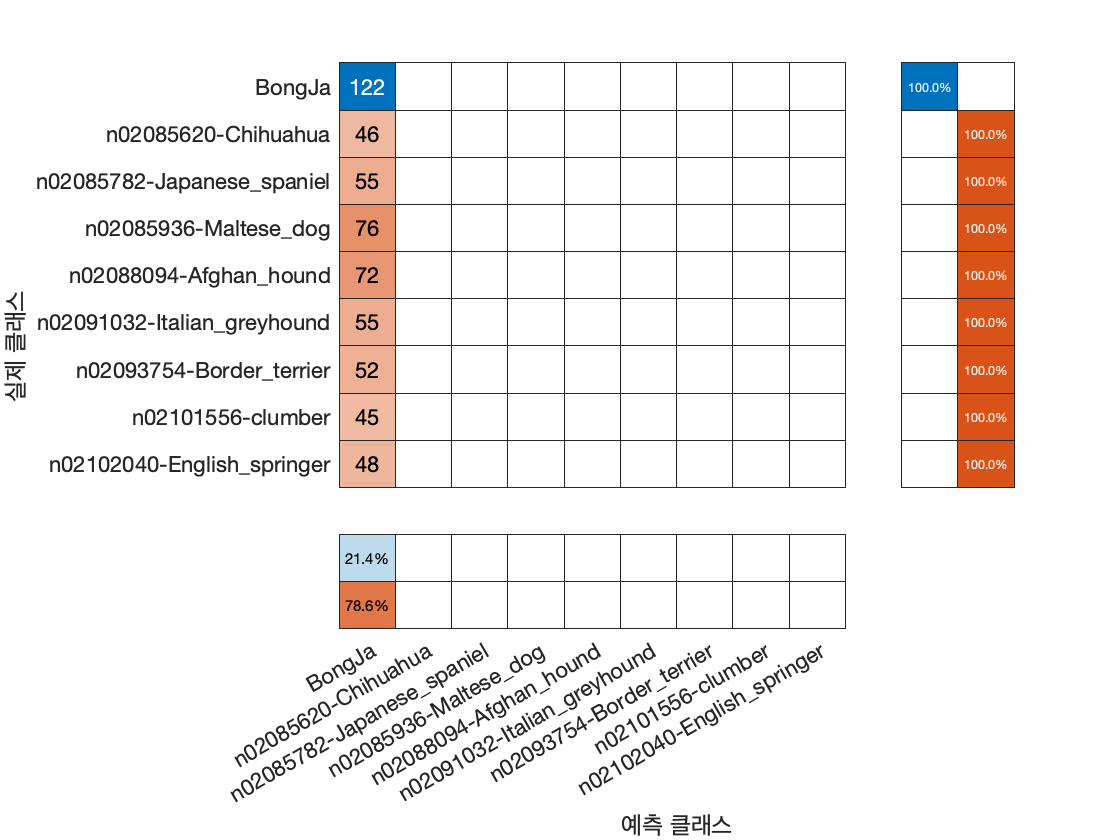

figure
confusionchart(cm, OutputCat, 'ColumnSummary', 'column-normalized', 'RowSummary', 'row-normalized')


nall = sum(sum(cm))

nall = 571

ndiag = sum(diag(cm))

ndiag = 122

myloss = (nall - ndiag) / nall

myloss = 0.7863

myloss2 = 1-ndiag/nall

myloss2 = 0.7863



save('FirstNet','FirstNet');